# Solution 12.3 - Solution for Example 12.3 from Week 7 notes.

% ADD NEW CODE HERE (1)

In the lecture we showed that after simplification for Example 12.3

$V_{\mathrm{o}\mathrm{u}\mathrm{t}} (s)=\frac{2s(s+3)}{s^3 +8s^2 +10s+4}\;$(1)

We will use MATLAB to factorize the denominator $D(s)$ of the equation into a linear and a quadratic factor.

Note that, when the denominator is factorized, equation (1) will be

$V_{\mathrm{o}\mathrm{u}\mathrm{t}} (s)=\frac{2s(s+3)}{(s-p_1 )(s-p_2 )(s-p_3 )}$ (2)

where $p_1 \;$is real and $p_2$ and $p_3 \;$are complex with $p_3 =p_2^*$ (the complex conjugate of $p_2$).

Declare the denominator of `Vout` to be a MATLAB vector

syms s 
Ds = s^3 + 8*s^2 + 10*s + 4

$$Ds = s^{3}+8\,s^{2}+10\,s+4$$

Convert `Ds` to a MATLAB polynomial using `sym2poly`

d = sym2poly(Ds)

d =      1     8    10     4


Find roots of $D\left(s\right)$

format long
p = roots(d)

p =  -6.570750563722639 + 0.000000000000000i
 -0.714624718138679 + 0.313161257350729i
 -0.714624718138679 - 0.313161257350729i


Store real pole as `p1`

p1 = p(1)

p1 =   -6.570750563722639


Find quadratic form

qs = expand((s - p(2))*(s - p(3)))

$$qs = s^{2}+\frac{804595903579775\,s}{562949953421312}+\frac{3086772113315577969665007046981}{5070602400912917605986812821504}$$

Simplify coefficients of `qs` and return a numerical polynomial vector

q = sym2poly(qs)

q =    1.000000000000000   1.429249436277358   0.608758460880276


## Now use inverse Laplace transform to solve

Define the factors of the denominator and rewrite `Vout` in factored form.

You will need `p1` and `q` from the previous section

% ADD NEW CODE HERE (2)

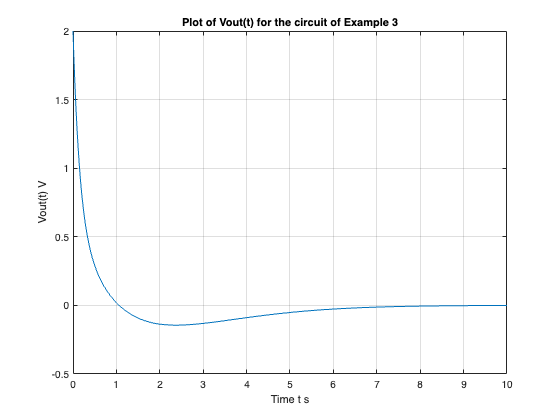

% % Plot result

t=0:0.01:10;
Vout = 1.36.*exp(-6.57.*t)+0.64.*exp(-0.715.*t).*cos(0.316.*t)-1.84.*exp(-0.715.*t).*sin(0.316.*t);
plot(t, Vout); grid
title('Plot of Vout(t) for the circuit of Example 3')
ylabel('Vout(t) V'),xlabel('Time t s')

## Alternative solution using transfer functions

Vout = tf(2*conv([1, 0],[1, 3]),[1, 8, 10, 4])

Vout =
 
       2 s^2 + 6 s
  ----------------------
  s^3 + 8 s^2 + 10 s + 4
 
Continuous-time transfer function.
Model Properties


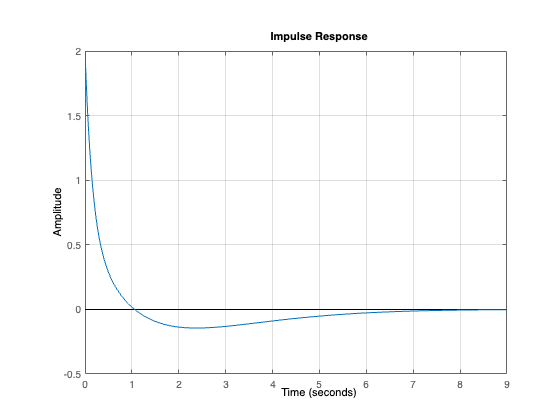

impulse(Vout), grid